clc,clear;
SFC = SignalFlowChart();
SFC.createSFC('Miller_OTA.txt')
[details, TF, dcGain, poles, zeros] = SFC.solveTF;
[newTF, p, z, DCgain] = SFC.simplifyTF(TF)

$$newTF = -\frac{{\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,\left(\frac{\mathrm{Cc}\,s}{{\mathrm{gm}}_{2}}-1\right)}{\left(\frac{s\,\left(C_{1}\,\mathrm{CL}+C_{1}\,\mathrm{Cc}+\mathrm{CL}\,\mathrm{Cc}\right)}{\mathrm{Cc}\,{\mathrm{gm}}_{2}}+1\right)\,\left(\mathrm{Cc}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,s+1\right)}$$

$$p = \left(\begin{array}{cc} -\frac{\mathrm{Cc}\,{\mathrm{gm}}_{2}}{C_{1}\,\mathrm{CL}+C_{1}\,\mathrm{Cc}+\mathrm{CL}\,\mathrm{Cc}} & -\frac{1}{\mathrm{Cc}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}} \end{array}\right)$$

$$z = \frac{{\mathrm{gm}}_{2}}{\mathrm{Cc}}$$

$$DCgain = {\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}$$

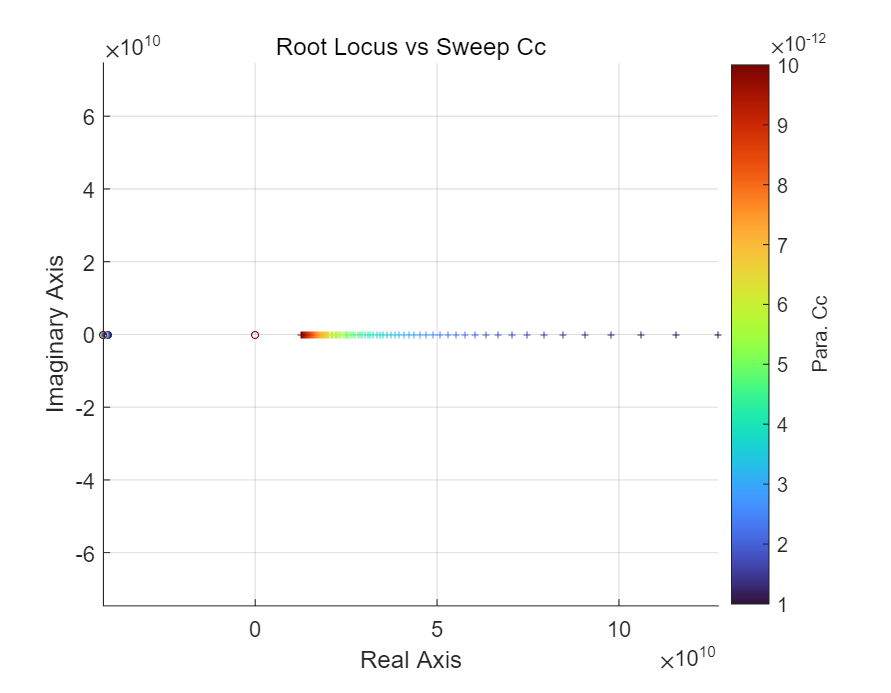

r = 包含以下字段的 struct :
     poles: [-1    -1]
     zeros: 4/(5*Cc)
    DCgain: 4400000


SFC.SFParser.registerValue('Miller_OTA.txt')
r = SFC.analysisTF(TF, 'RLocus', 1e-12:1e-13:10e-12)

SFC = SignalFlowChart();
SFC.createSFC('Cascode_compensation.txt')
[details, TF, dcGain, poles, zeros] = SFC.solveTF;
[newTF, p, z, DCgain] = SFC.simplifyTF(TF)

$$newTF = \begin{array}{l} -\frac{{\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}\,\left(\frac{\mathrm{Cc}\,s}{{\mathrm{gm}}_{2}\,{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{3}}-1\right)\,\left(C_{1}\,{\mathrm{ro}}_{3}\,s+1\right)}{\left(\frac{C_{1}\,\mathrm{CL}\,\mathrm{Cc}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}\,s}{\sigma_{1}}+1\right)\,\left(\frac{s\,\sigma_{1}}{{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{3}\,\left(C_{1}+\mathrm{Cc}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}\right)}+1\right)\,\left({\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{3}\,s\,\left(C_{1}+\mathrm{Cc}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}\right)+1\right)}\\ \mathrm{where}\\ \sigma_{1}=C_{1}\,\mathrm{CL}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+C_{1}\,\mathrm{CL}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}+C_{1}\,\mathrm{Cc}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+C_{1}\,\mathrm{Cc}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{3}+C_{1}\,\mathrm{Cc}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}+\mathrm{CL}\,\mathrm{Cc}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+C_{1}\,\mathrm{CL}\,{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}+C_{1}\,\mathrm{Cc}\,{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3} \end{array}$$

$$p = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sigma_{1}}{C_{1}\,\mathrm{CL}\,\mathrm{Cc}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}} & -\frac{{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{3}\,\left(C_{1}+\mathrm{Cc}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}\right)}{\sigma_{1}} & -\frac{1}{{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{3}\,\left(C_{1}+\mathrm{Cc}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{1}\,\mathrm{CL}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+C_{1}\,\mathrm{CL}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}+C_{1}\,\mathrm{Cc}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+C_{1}\,\mathrm{Cc}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{3}+C_{1}\,\mathrm{Cc}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}+\mathrm{CL}\,\mathrm{Cc}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+C_{1}\,\mathrm{CL}\,{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}+C_{1}\,\mathrm{Cc}\,{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3} \end{array}$$

$$z = \left(\begin{array}{cc} -\frac{1}{C_{1}\,{\mathrm{ro}}_{3}} & \frac{{\mathrm{gm}}_{2}\,{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{3}}{\mathrm{Cc}} \end{array}\right)$$

$$DCgain = {\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{gm}}_{3}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}$$

SFC = SignalFlowChart();
SFC.createSFC('ssf.txt')
[details, TF, dcGain, poles, zeros] = SFC.solveTF;
[newTF, p, z, DCgain] = SFC.simplifyTF(TF)

$$newTF = \begin{array}{l} \frac{{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}\,\left(\frac{\mathrm{Cd}\,s}{\mathrm{Rd}}+1\right)\,\left({\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}+1\right)\,\left(\frac{\mathrm{Cd}\,{\mathrm{Rd}}^{2}\,s}{{\mathrm{gm}}_{2}}-1\right)}{\left(\frac{s\,\sigma_{1}}{\mathrm{Rd}\,{\mathrm{gm}}_{1}}+1\right)\,\left(\frac{\mathrm{CL}\,\mathrm{Cd}\,s}{\sigma_{1}}+1\right)\,\left(\frac{\mathrm{Cd}\,{\mathrm{Rd}}^{2}\,{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}\,s}{{\mathrm{gm}}_{2}\,\left({\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}+1\right)}-1\right)\,\left({\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}+{\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}-1\right)}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Cd}\,{\mathrm{gm}}_{1}+\mathrm{CL}\,\mathrm{Rd} \end{array}$$

$$p = \left(\begin{array}{ccc} -\frac{\mathrm{Cd}\,{\mathrm{gm}}_{1}+\mathrm{CL}\,\mathrm{Rd}}{\mathrm{CL}\,\mathrm{Cd}} & -\frac{\mathrm{Rd}\,{\mathrm{gm}}_{1}}{\mathrm{Cd}\,{\mathrm{gm}}_{1}+\mathrm{CL}\,\mathrm{Rd}} & \frac{{\mathrm{gm}}_{2}\,\left({\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}+1\right)}{\mathrm{Cd}\,{\mathrm{Rd}}^{2}\,{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}} \end{array}\right)$$

$$z = \left(\begin{array}{cc} -\frac{\mathrm{Rd}}{\mathrm{Cd}} & \frac{{\mathrm{gm}}_{2}}{\mathrm{Cd}\,{\mathrm{Rd}}^{2}} \end{array}\right)$$

$$DCgain = \frac{{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}\,\left({\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}+1\right)}{{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}+{\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}-1}$$